p = 1

p = 1

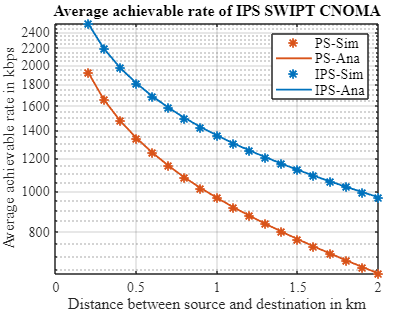

p = 1

p = 1

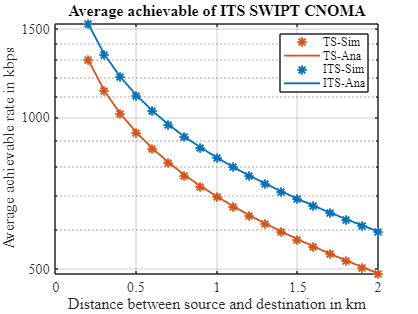

clc
close all
clear
warning off
fc =0.5;
T=1;
rok = 0.25; % Power Splitting factor
tou = 0.45; % Time Switching Factor
dsd=0.2:0.1:2;% Distance between Sourse and 
ds=length(dsd);
r=0.1;
theta=pi/3;
dsd=dsd';
dsr=zeros(1,ds)+r;
dsr = dsr';
drd=sqrt(dsd.^2+dsr.^2 - (2*dsd.*dsr.*cos(theta)));
b3=10^(1.976); 
bet=10^(-0.59);
B3=b3.*dsd.^(-bet);
cost=100;
B33=B3/cost;
BB3= b3.*dsr.^(-bet);
BB33=BB3/cost;
fl=ones(ds,1).*fc;
ITER=400;
% Frequecy ranges without Additinal Bandwidth
for i =1:cost
    fd11(:,i)= fc+((i-1).*B33);
    
end

for i =1:cost
    fd21(:,i)= fc+((i-1).*BB33);
    
end
% Additional Bandwidth CAlculation 

FADD21(:,1) = fd11(:,100) ;
FADD21(:,2) = fd21(:,100);
FADD31 = (FADD21(:,2) - FADD21(:,1))/99;

for i=1:length(dsd)
FADD41(i,:) = FADD21(i,1):FADD31(i,1):FADD21(i,2); %% Frequecy ranges with Additional bandwidth
end
